# **IO113-20 - Analog Output and Digital Loopback example**

This example demonstrates how to configure and use two analog output channels in single ended mode and how to perform a digital loopback on the IO113-20 I/O Module.

The IO113-20 I/O module provides 8 single-ended or 8 differential 20-bit analog outputs and 8 bidirectional digital TTL I/O lines.-

This example runs on the IO113-20 I/O Module. The I/O Modules blocks can be replaced in the model to also work with the IO113 I/O Module

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO113-20 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

- Oscilloscope 

### Test Setup

On the terminal board of the analog I/O module, connect Analog Outputs 1 and 2 to two separate channel of your lab oscilloscope, Finally, connect the digital pin as described below.

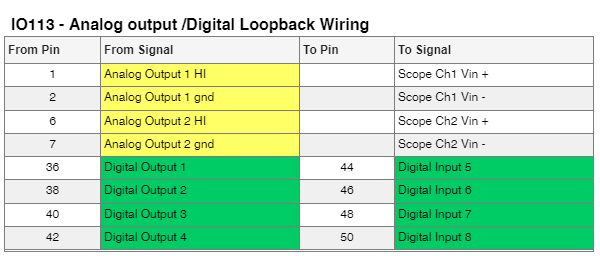

[IO113 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io113_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO113_20_AnalogOutputDigitalLoopback';
open_system(modelName);

### Model Description

The Simulink model features the [IO113-20 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io113_setup), [IO113-20 Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io113_analog_output), [IO113-20 Digital Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io113_digital_input) and [IO113-20 Digital Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io113_digital_output) blocks. Analog Outputs 1 and 2, as well as Digital Inputs and Outputs 1 and 8 are enabled in the [IO113-20 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io113_setup) block. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.setStopTime(10);
tg.start;

% The real-time application on the target machine will automatically stop after 10 seconds

### Check the Results

By opening the scope in the simulink model you will be able to inspect the digital signals.

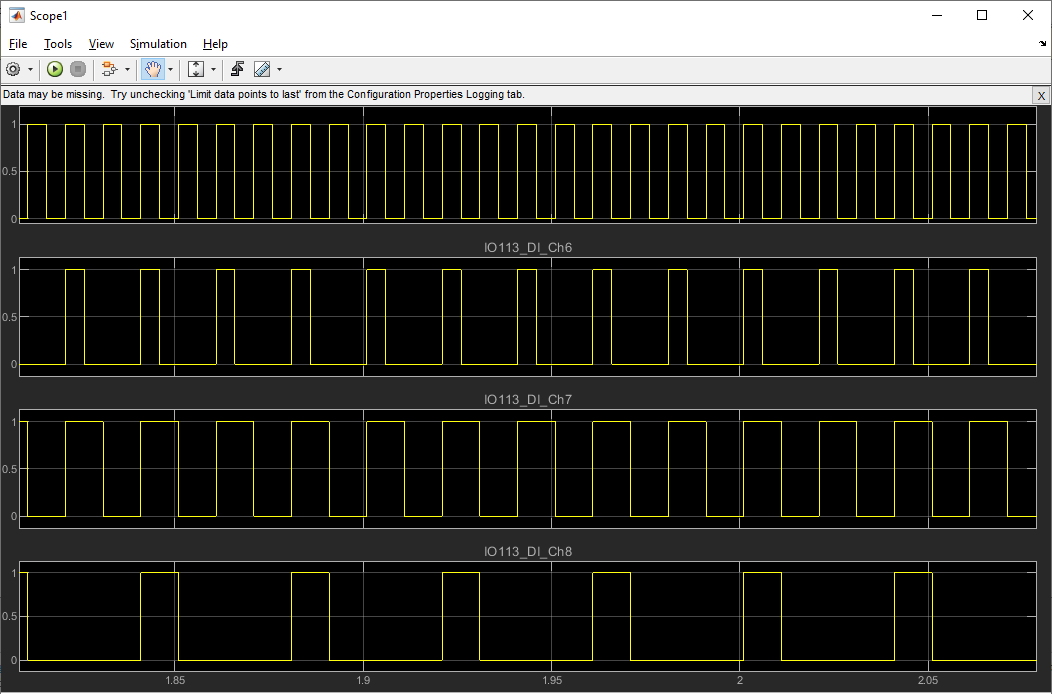

On your lab scope you will see the signals as configured in the simulink model

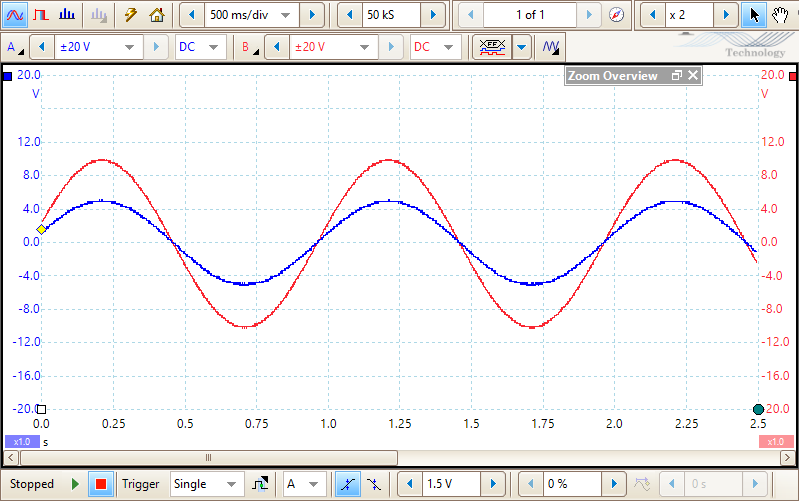

## Additional References

- [IO113-20 documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io113)